# TentSim Coincidence Analysis

Uses the output of Tentsim_BAS.mlx to form 2D color maps basec on coincident events 

Dependancies:

NOTES:

Start with Binning_override   and   Range_override  unchecked. Run w/o color correction first to see what the Red:Blue ratio looks like for calibrator beads. Next apply correction using default damping factor. Assess the symmetry and quality of the PCH and BAS curves (following characterisitic function slope, symmetric about center, large low amp tail?). Larger damping means less color correction.

Finally, based on sampling, PCH and BAS curves choose a suitable range and binning

FUTURE:

## Initialize

clear               % Clear all workspace saved variables

% UPDATE when code is revised
versionnum= 'v1p3';
disp(['Version information and details of modeling at bottom of mlx code ' ...
    'below the Information function'])

Version information and details of modeling at bottom of mlx code below the Information function


## Load parameters if used

Load variables and parameters stored in the output of Tentsim_Preprocess.mlx

Currently not used

readCOINparams =  false

readCOINparams = logical
   0



if readCOINparams

disp('Select COINCIDENCE PARAMETER file')
[CoinFileName,CoinPathName] = uigetfile('*.txt','Select COINCIDENCE PARAMETER file ');
disp(strcat('Using COINCIDENCE parameter file path: ',CoinPathName));
disp(strcat('Using COINCIDENCE parameter file: ',CoinFileName));


paramfile=strcat(CoinPathName,CoinFileName);
readmeCOIN = importdata(paramfile);
%%% Examples but not real items
% preproparams=readmeBAS.data;  %vector of parameters for processing
% catfilenames=readmeBAS.textdata(6:end-1,1); %last line is column headings
% colheader=readmeBAS.textdata(end,:);  %has column header info
% 
% offsetA=readmeBAS.data(1);  %0 = no offset, 1 = subtr mean, 2 = subtr median, 3 = subtr rms 
% offsetB=readmeBAS.data(2);
% smooth=readmeBAS.data(3); %logical; smoothing of raw event histogram before BAS analysis
% showfigs=readmeBAS.data(4); %logical; show or not plots of the BAS fitting to histogram

end

## Load previous BAS result data in .mat file 

disp('Select BAS .mat result file')

Select BAS .mat result file


[BasFileName,BasPathName] = uigetfile('*.mat','Select BAS .mat result file ');
disp(strcat('Using BAS file: ',BasPathName,BasFileName));

Using BAS file:/Users/JP/Desktop/Aggregation/BAS2022/DanielDissagregationData/LabeledAggData30min/BAS_v1p4_06Jan22-180428/BAS_v1p4Preprocess_v1p4Preparams10runs_30min.txt06Jan22-175126.mat06Jan22-180428RESULTS.mat


load(strcat(BasPathName,BasFileName))




## Visualize Red:Blue ratio vs blue intensity to decide about color correction

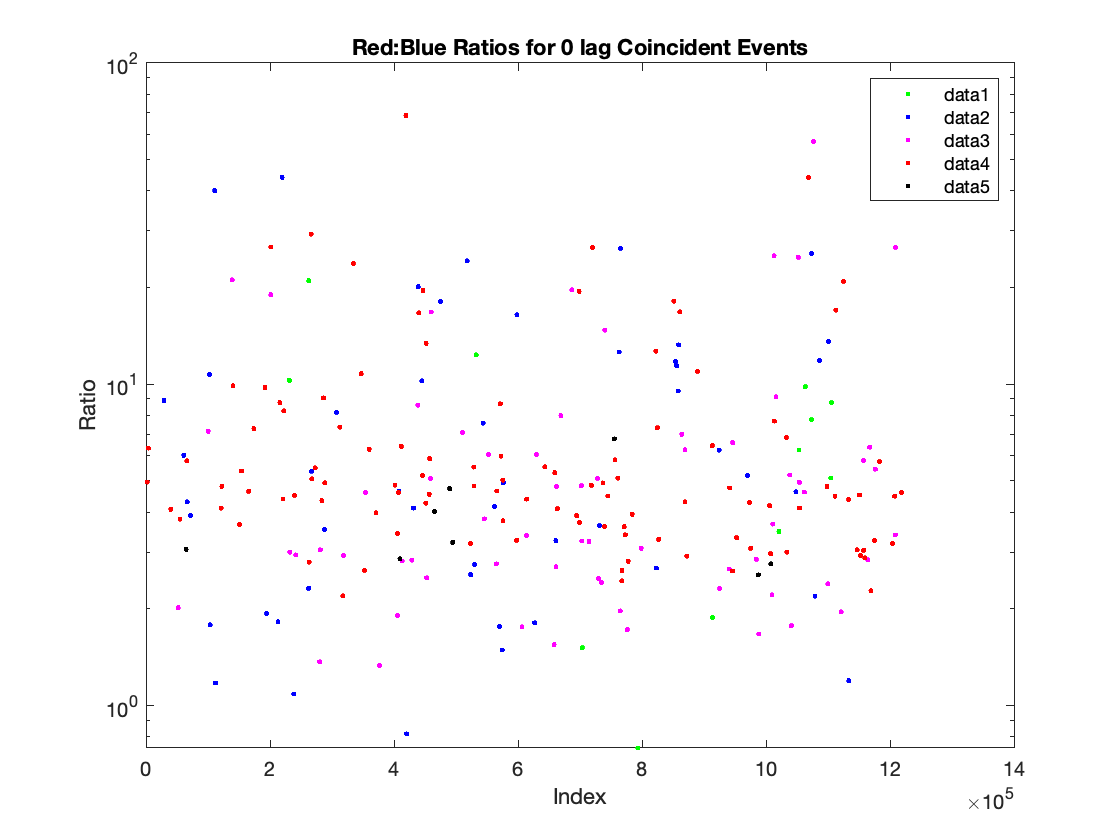

% Visualize how ratio value (Red:Blue) relates to blue intensity
%Look at 0 lag coincidence as general indicator; consider 5 bands
%Assumes at least factor of 32 in dynamic range from UB in A channel

qq0= find(handlesA.strikeamp > 3*handlesA.UB/4  ...
    & handlesB.strikeamp > 0 ) ; %top 1/4 of spikes
qq1= find(handlesA.strikeamp > handlesA.UB/2  ...
    & handlesB.strikeamp > 0 ) ; %top 1/2 of spikes
b1=(handlesA.UB/2 + handlesA.UB)/2;
qq2= find((handlesA.strikeamp < handlesA.UB/2) & (handlesA.strikeamp >handlesA.UB/8)...
    & handlesB.strikeamp > 0 );
b2=(handlesA.UB/2 + handlesA.UB/8)/2;
qq3= find((handlesA.strikeamp < handlesA.UB/8) & (handlesA.strikeamp >handlesA.UB/32)...
    & handlesB.strikeamp > 0 );
b3=(handlesA.UB/8 + handlesA.UB/32)/2;
qq4= find((handlesA.strikeamp < handlesA.UB/32) & (handlesA.strikeamp >2*handlesA.spthresh)...
    & handlesB.strikeamp > 0 );
b4=(handlesA.UB/32 + 2*handlesA.spthresh)/2;
qq5= find((handlesA.strikeamp < 2*handlesA.spthresh) & (handlesA.strikeamp >handlesA.spthresh)...
    & handlesB.strikeamp > 0 );
b5=(2*handlesA.spthresh + handlesA.spthresh)/2;

idx=[1:length(handlesA.strikeamp)]; %index for plotting
figure
ratio0=handlesB.strikeamp(qq0)./handlesA.strikeamp(qq0);
ratio1=handlesB.strikeamp(qq1)./handlesA.strikeamp(qq1);
ratio2=handlesB.strikeamp(qq2)./handlesA.strikeamp(qq2);
ratio3=handlesB.strikeamp(qq3)./handlesA.strikeamp(qq3);
ratio4=handlesB.strikeamp(qq4)./handlesA.strikeamp(qq4);
ratio5=handlesB.strikeamp(qq5)./handlesA.strikeamp(qq5);

semilogy(idx(qq2),ratio2,'.g');
title('Red:Blue Ratios for 0 lag Coincident Events');
xlabel('Index');
ylabel('Ratio');
legend
hold on
semilogy(idx(qq3),ratio3,'.b');
semilogy(idx(qq4),ratio4,'.m');
semilogy(idx(qq5),ratio5,'.r');
%semilogy(idx(qq0),ratio0,'.c');
semilogy(idx(qq1),ratio1,'.k');
hold off


mqq1=median(ratio1)

mqq1 = 3.1398

length(ratio1)

ans = 8

mqq2=median(ratio2)

mqq2 = 6.9972

length(ratio2)

ans = 12

mqq3=median(ratio3)

mqq3 = 4.9388

length(ratio3)

ans = 49

mqq4=median(ratio4)

mqq4 = 3.3951

length(ratio4)

ans = 65

mqq5=median(ratio5)

mqq5 = 4.7046

length(ratio5)

ans = 110

meanratios=mean([ratio1,ratio2,ratio3,ratio4,ratio5])

meanratios = 7.5028

rmsratios=rms([ratio1,ratio2,ratio3,ratio4,ratio5]-meanratios)

rmsratios = 8.6933



prompt='Do you want to apply color correction?';
ccorans = inputdlg(prompt); %creates cell array
ccorans=string(ccorans{1});

switch ccorans
    case {'Y','y','yes','Yes','YES'}
      colorcorrection = true 
              
        prompt='Use default tetraspec calibration exponent (-0.165) (no = fit new one)?';
        defcc = inputdlg(prompt); %creates cell array
        defcc=string(defcc{1});
        switch defcc
            case {'Y','y','yes','Yes','YES'}
               bb=[b1,b2,b3,b4,b5]';
              mq=[mqq1,mqq2,mqq3,mqq4,mqq5]';
              fo = fitoptions('Method','NonlinearLeastSquares',...
                       'Lower',[0,0],...
                       'Upper',[Inf,Inf],...
                       'StartPoint',[1 0]);
              ft = fittype('a*x^n+b','problem','n','options',fo);  %'problem','b',
              [curve2,gof2] = fit(bb,mq,ft,'problem',-0.165)  %,'problem',mqq1
              plot(bb,mq,'ok')
              hold on
              plot(curve2,'b')
              title('Color Correction Exponential Model')
              xlabel('intensity A channel')
              ylabel('Red:blue ratio')
              hold off
            
            otherwise
              
              % Determine model fit to 5 ratio bins
              bb=[b1,b2,b3,b4,b5]';
              mq=[mqq1,mqq2,mqq3,mqq4,mqq5]';
              fo = fitoptions('Method','NonlinearLeastSquares',...
                       'Lower',[0,0, -5],...
                       'Upper',[Inf,Inf, 0],...
                       'StartPoint',[1 0 -1]);
              ft = fittype('a*x^n+b','options',fo);  %'problem','b',
              [curve2,gof2] = fit(bb,mq,ft)  %,'problem',mqq1
              plot(bb,mq,'ok')
              hold on
              plot(curve2,'b')
              title('Color Correction Exponential Model')
              xlabel('intensity A channel')
              ylabel('Red:blue ratio')
              hold off
              
        end
      % Include A channel subthreshold events to help with undersampling
      % due to noise
      handlesA.strikefull = handlesA.strike + handlesA.subthreshstrike;
      handlesA.strikeampfull = handlesA.strikeamp + handlesA.subthreshstrikeamp;
 
       % Apply correction model (heuristic)
       % Damping factor is a gain factor for correction where 1 means full
       % correction and larger numbers reduce correction. Basically divides
       % correction factor by the damping factor
       prompt='Damping factor for color correction (1.3 is a good guess)?';
       damping = inputdlg(prompt); %creates cell array
       damping=str2double(damping{1});

       rationorm=mqq1
       cccorrection = curve2(handlesA.strikeampfull)/rationorm;
       cccorrection(~isfinite(cccorrection)) = 0;       
       qqcc=(cccorrection == 0);
       cccorrection = (cccorrection'-rationorm)/damping + rationorm;
       
       handlesA.strikeampfull=handlesA.strikeampfull.*cccorrection;
%        % Add random noise of variance 1 and mean 0 to schmear bit discretization
       handlesA.strikeampfull =  handlesA.strikeampfull + randn(1,length(cccorrection));
       handlesA.strikeampfull(handlesA.strikeampfull < handlesA.spthresh) = 0;


      % Now remove anything below spthresh amplitude
      cutqq= (handlesA.strikeampfull < handlesA.spthresh) ;
      handlesA.strikeampfull(cutqq) = 0;
      handlesA.strikefull(cutqq) = 0;
      
      % Find new rms about mean of corrected ratio data using original data location qq# 
      % should be reduced from above. Basic housekeeping but not needed.
        ccratio1=handlesB.strikeamp(qq1)./handlesA.strikeampfull(qq1);
        ccratio2=handlesB.strikeamp(qq2)./handlesA.strikeampfull(qq2);
        ccratio3=handlesB.strikeamp(qq3)./handlesA.strikeampfull(qq3);
        ccratio4=handlesB.strikeamp(qq4)./handlesA.strikeampfull(qq4);
        ccratio5=handlesB.strikeamp(qq5)./handlesA.strikeampfull(qq5);
        ccmeanratios=mean([ccratio1,ccratio2,ccratio3,ccratio4,ccratio5])
        ccrmsratios=rms([ccratio1,ccratio2,ccratio3,ccratio4,ccratio5]-ccmeanratios)

      
      % Now replace handlesA.strikeamp with this scaled data
      handlesA.strikeamp = handlesA.strikeampfull;
      handlesA.strike = handlesA.strikefull;
      
    otherwise
      colorcorrection = false  
end

colorcorrection = logical
   0


## Find coincidentevents in different size windows using A channel as fiducial bin reference

Check lags of 0,+/-1, +/-2  ;    TBD: Need to handle artificial endpoint coincidence due to wrapping 


% % Note: any minimum threshold that was applied before still holds:
% % see handlesA.subthresh  and handlesB.subthresh

binindex=[1:length(handlesA.strike)]; %data array length (i.e. number of bins)

% 0 Lag
costrike=logical(handlesA.strike.*handlesB.strike);  %coincident A and B events (symmetric)
index0=binindex(costrike);

missindex0_A=logical(handlesA.strike - costrike);  % locate 0 lag non-coincident events in both channels
missindex0_B=logical(handlesB.strike - costrike);

winmaxA0=(handlesA.strikeamp.*costrike); % Amplitudes of coincident events
winmaxB0=(handlesB.strikeamp.*costrike);

% +1/-1 Lag
costrikeAp1B=logical(handlesA.strike.*circshift(handlesB.strike,1));  % A events with B event +/-1 away
indexAp1B=binindex(costrikeAp1B);
costrikeAn1B=logical(handlesA.strike.*circshift(handlesB.strike,-1));
indexAn1B=binindex(costrikeAn1B);
allindexA10B=sort([indexAp1B,indexAn1B,index0]);
qq=(allindexA10B-circshift(allindexA10B,-1))~=0;  %need to remove redundant indices when multiple events too close
allindexA10B=allindexA10B(qq);

missindex10_A=logical(handlesA.strike - costrike - costrikeAn1B - costrikeAp1B);  % locate 0 lag non-coincident events in both channels
missindex10_B=logical(handlesB.strike - costrike - circshift(costrikeAn1B,1) - circshift(costrikeAp1B,-1));  % locate 0 lag non-coincident events in both channels


windatB10=[(circshift(handlesB.strikeamp,-1).*costrikeAn1B)',(handlesB.strikeamp.*costrike)',(circshift(handlesB.strikeamp,1).*costrikeAp1B)'];
winmaxB10=max(windatB10,[],2)'; %Finds max B amplitude for coinicident events in window of 0,+/-1
winmaxAdatBsh10=handlesA.strikeamp(allindexA10B);

% +2/-2 Lag
costrikeAp2B=logical(handlesA.strike.*circshift(handlesB.strike,2));  % A events with B event +/-2 away
indexAp2B=binindex(costrikeAp2B);
costrikeAn2B=logical(handlesA.strike.*circshift(handlesB.strike,-2));
indexAn2B=binindex(costrikeAn2B);
allindexA210B=sort([indexAp2B,indexAn2B,allindexA10B]);
qq=(allindexA210B-circshift(allindexA210B,-1))~=0;  %need to remove redundant indices when multiple events too close
allindexA210B=allindexA210B(qq);

missindex210_A=logical(handlesA.strike - costrike - costrikeAn1B - costrikeAp1B - costrikeAn2B - costrikeAp2B);  % locate 0 lag non-coincident events in both channels
missindex210_B=logical(handlesB.strike - costrike - circshift(costrikeAn1B,1) - circshift(costrikeAp1B,-1) ...
    - circshift(costrikeAn2B,2) - circshift(costrikeAp2B,-2));  % locate 0 lag non-coincident events in both channels

windatB210=[(circshift(handlesB.strikeamp,-2).*costrikeAn2B)',windatB10,(circshift(handlesB.strikeamp,2).*costrikeAp2B)'];
winmaxB210=max(windatB210,[],2)'; %Finds max B amplitude for coinicident events in window of 0,+/-1,+/-2
winmaxAdatBsh210=handlesA.strikeamp(allindexA210B);



## Option to rebin with coarser binning since now fewer events per bin

%Initialize BAS results
nbinsA = length(logedgeA); nbinsB = length(logedgeB); 


minedgeA=min(logedgeA);
maxedgeA=max(logedgeA);  %factor of 2 useful for visual padding at large amplitudes
minedgeB=min(logedgeB);
maxedgeB=max(logedgeB);

%Default
edgemnA=(log10(minedgeA));
edgemxA=(log10(maxedgeA))

edgemxA = 3.6082

edgemnB=(log10(minedgeB));
edgemxB=(log10(maxedgeB));

Binning_override = false  %Choose a non-default binning

Binning_override = logical
   0


Range_override = false  %Choose a non-default range

Range_override = logical
   0


    
if Range_override
    minedgeA = 80
    maxedgeA = 12000
    minedgeB = 80
    maxedgeB = 12000
    edgemnA=(log10(minedgeA));
    edgemxA=(log10(maxedgeA));
    edgemnB=(log10(minedgeB));
    edgemxB=(log10(maxedgeB));

end
  
if Binning_override

  nbinsA =14
  nbinsB =14

end


logedgeArb = logspace(edgemnA,edgemxA,nbinsA);
logedgeBrb = logspace(edgemnB,edgemxB,nbinsB);

% 2D array for contour plotting
[X,Y] = meshgrid(logedgeArb(1:end-1),logedgeBrb(1:end-1));



## Streamlined version

## 2D binning of coincident events

%Sort events into bins
%----------------------------
%0 Lag  -  cumratmap0BA is the number of data value pairs in a bin
%[cumratmap0BA,Xedges,Yedges,binA0,binB0] = histcounts2(winmaxA0,winmaxB0,logedgeArb,logedgeBrb);
%Estimate experimental uncertainty in each bin by breaking up data into
%quarters
quar=fix(length(winmaxA0)/4);
[n0q1,Xedges,Yedges,binA0,binB0] = histcounts2(winmaxA0(1:quar),winmaxB0(1:quar),logedgeArb,logedgeBrb);
[n0q2,Xedges,Yedges,binA0,binB0] = histcounts2(winmaxA0(quar+1:2*quar),winmaxB0(quar+1:2*quar),logedgeArb,logedgeBrb);
[n0q3,Xedges,Yedges,binA0,binB0] = histcounts2(winmaxA0(2*quar+1:3*quar),winmaxB0(2*quar+1:3*quar),logedgeArb,logedgeBrb);
[n0q4,Xedges,Yedges,binA0,binB0] = histcounts2(winmaxA0(3*quar+1:end),winmaxB0(3*quar+1:end),logedgeArb,logedgeBrb);
avgn0BA =(n0q1+n0q2+n0q3+n0q4); %total number of events
unc0BA=sqrt(((n0q1-avgn0BA/4).^2+(n0q2-avgn0BA/4).^2+(n0q3-avgn0BA/4).^2+(n0q4-avgn0BA/4).^2)/4);
pnavgn0BA=sqrt(avgn0BA); %poisson counting noise for comparison

%Bin rations and uncertainty in binned values
Avalmap0BA=avgn0BA*0;  Avalmap0BAunc=avgn0BA*0;
Bvalmap0BA=avgn0BA*0;  Bvalmap0BAunc=avgn0BA*0;
[n0,Xedges,Yedges,binA0,binB0] = histcounts2(winmaxA0,winmaxB0,logedgeArb,logedgeBrb);
for i=1:size(avgn0BA,1)
    for  j=1:size(avgn0BA,2)
        Avalmap0BA(i,j)= mean(winmaxA0(binA0==i & binB0==j));
        Avalmap0BAunc(i,j)= std(winmaxA0(binA0==i & binB0==j));
        Bvalmap0BA(i,j)= mean(winmaxB0(binA0==i & binB0==j));
        Bvalmap0BAunc(i,j)= std(winmaxB0(binA0==i & binB0==j));
    end
end


%----------------------------
%0,+/-1 Lags
tempB10=winmaxB10(winmaxB10>0);
%[cumratmap10BA,Xedges,Yedges,binA10,binB10] = histcounts2(winmaxAdatBsh10,tempB10,logedgeArb,logedgeBrb);
%Estimate experimental uncertainty in each bin by breaking up data into
%quarters
quar=fix(length(winmaxAdatBsh10)/4);
[n10q1,Xedges,Yedges,binA10,binB10] = histcounts2(winmaxAdatBsh10(1:quar),tempB10(1:quar),logedgeArb,logedgeBrb);
[n10q2,Xedges,Yedges,binA10,binB10] = histcounts2(winmaxAdatBsh10(quar+1:2*quar),tempB10(quar+1:2*quar),logedgeArb,logedgeBrb);
[n10q3,Xedges,Yedges,binA10,binB10] = histcounts2(winmaxAdatBsh10(2*quar+1:3*quar),tempB10(2*quar+1:3*quar),logedgeArb,logedgeBrb);
[n10q4,Xedges,Yedges,binA10,binB10] = histcounts2(winmaxAdatBsh10(3*quar+1:end),tempB10(3*quar+1:end),logedgeArb,logedgeBrb);
avgn10BA =(n10q1+n10q2+n10q3+n10q4); %total number of events
unc10BA=sqrt(((n10q1-avgn10BA/4).^2+(n10q2-avgn10BA/4).^2+(n10q3-avgn10BA/4).^2+(n10q4-avgn10BA/4).^2)/4);
pnavgn10BA=sqrt(avgn10BA); %poisson counting noise for comparison

%Uncertainty in bins
Avalmap10BA=avgn10BA*0;  Avalmap10BAunc=avgn10BA*0;
Bvalmap10BA=avgn10BA*0;  Bvalmap10BAunc=avgn10BA*0;
[n10,Xedges,Yedges,binA10,binB10] = histcounts2(winmaxAdatBsh10,tempB10,logedgeArb,logedgeBrb);
for i=1:size(avgn10BA,1)
    for  j=1:size(avgn10BA,2)
        Avalmap10BA(i,j)= mean(winmaxAdatBsh10(binA10==i & binB10==j));
        Avalmap10BAunc(i,j)= std(winmaxAdatBsh10(binA10==i & binB10==j));
        Bvalmap10BA(i,j)= mean(tempB10(binA10==i & binB10==j));
        Bvalmap10BAunc(i,j)= std(tempB10(binA10==i & binB10==j));
    end
end


%----------------------------
%0,+/-1, +/-2 Lags
tempB210=winmaxB210(winmaxB210>0);
%[cumratmap210BA,Xedges,Yedges,binA210,binB210] = histcounts2(winmaxAdatBsh210,tempB210,logedgeArb,logedgeBrb);
%Estimate experimental uncertainty in each bin by breaking up data into
%quarters
quar=fix(length(winmaxAdatBsh210)/4);
[n210q1,Xedges,Yedges,binA210,binB210] = histcounts2(winmaxAdatBsh210(1:quar),tempB210(1:quar),logedgeArb,logedgeBrb);
[n210q2,Xedges,Yedges,binA210,binB210] = histcounts2(winmaxAdatBsh210(quar+1:2*quar),tempB210(quar+1:2*quar),logedgeArb,logedgeBrb);
[n210q3,Xedges,Yedges,binA210,binB210] = histcounts2(winmaxAdatBsh210(2*quar+1:3*quar),tempB210(2*quar+1:3*quar),logedgeArb,logedgeBrb);
[n210q4,Xedges,Yedges,binA210,binB210] = histcounts2(winmaxAdatBsh210(3*quar+1:end),tempB210(3*quar+1:end),logedgeArb,logedgeBrb);
avgn210BA =(n210q1+n210q2+n210q3+n210q4); %total number of events
unc210BA=sqrt(((n210q1-avgn210BA/4).^2+(n210q2-avgn210BA/4).^2+(n210q3-avgn210BA/4).^2+(n210q4-avgn210BA/4).^2)/4);
pnavgn210BA=sqrt(avgn210BA); %poisson counting noise for comparison

%Uncertainty in bins

Avalmap210BA=avgn210BA*0;  Avalmap210BAunc=avgn210BA*0;
Bvalmap210BA=avgn210BA*0;  Bvalmap210BAunc=avgn210BA*0;
[n210,Xedges,Yedges,binA210,binB210] = histcounts2(winmaxAdatBsh210,tempB210,logedgeArb,logedgeBrb);
for i=1:size(avgn210BA,1)
    for  j=1:size(avgn210BA,2)
        Avalmap210BA(i,j)= mean(winmaxAdatBsh210(binA210==i & binB210==j));
        Avalmap210BAunc(i,j)= std(winmaxAdatBsh210(binA210==i & binB210==j));
        Bvalmap210BA(i,j)= mean(tempB210(binA210==i & binB210==j));
        Bvalmap210BAunc(i,j)= std(tempB210(binA210==i & binB210==j));
    end
end

% Define 2D array for intensity values using A channel
% May need to fix length issue associated with edges vs bin middle : end-1
IArat2D=repmat(logedgeArb(1:end-1),length(logedgeBrb(1:end-1)),1)';   %IArat2D(i,:) gives ith row, all col = logedgeArb




## Display intensity distribution of non-coincident data using BAS processing binning

Show missed conicidence fraction per bin for each lag window case

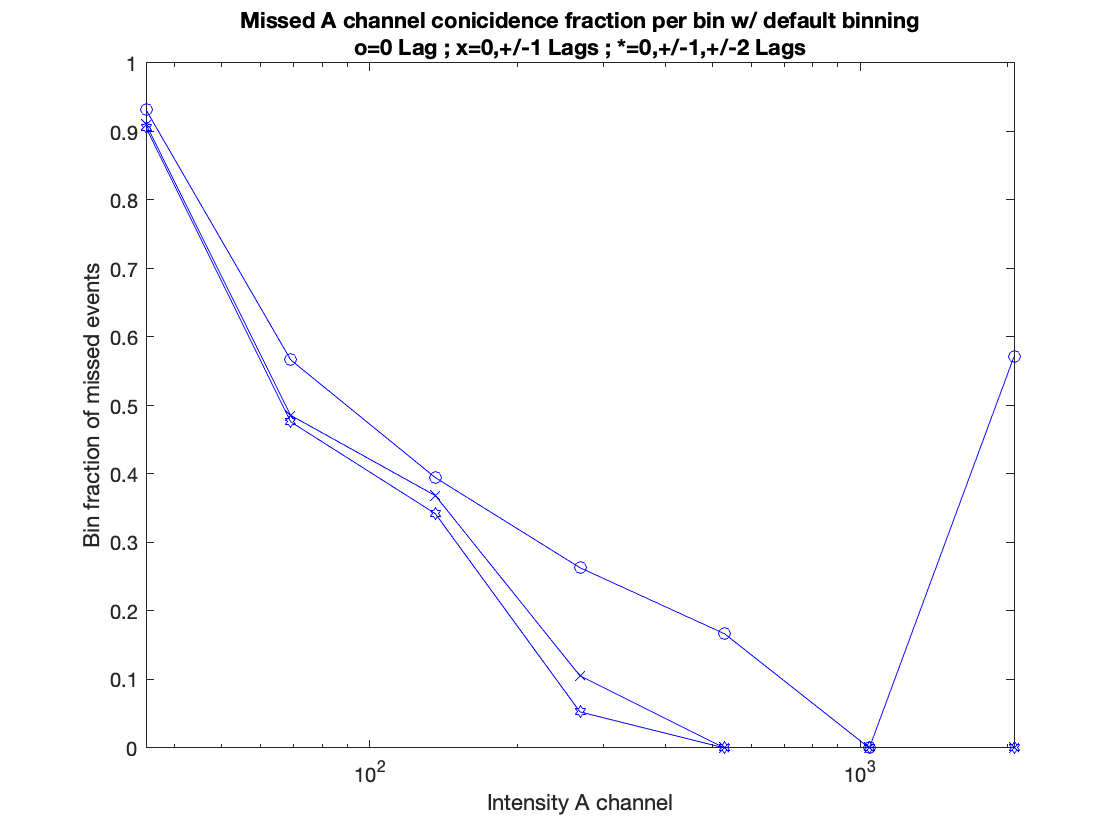

figure
[missA0_n,edges]=histcounts(handlesA.strikeamp(missindex0_A),logedgeA);
semilogx(logedgeA(1:end-1),missA0_n./nA(1:end-1),'-ob'); 
hold on
[missA10_n,edges]=histcounts(handlesA.strikeamp(missindex10_A),logedgeA);
semilogx(logedgeA(1:end-1),missA10_n./nA(1:end-1),'-xb'); 
[missA210_n,edges]=histcounts(handlesA.strikeamp(missindex210_A),logedgeA);
semilogx(logedgeA(1:end-1),missA210_n./nA(1:end-1),'-hb'); 

subtitle=strcat("o=0 Lag ; x=0,+/-1 Lags ; *=0,+/-1,+/-2 Lags");
title({'Missed A channel conicidence fraction per bin w/ default binning';subtitle})
xlabel('Intensity A channel')
ylabel('Bin fraction of missed events')
ylim([0,1]);  
hold off

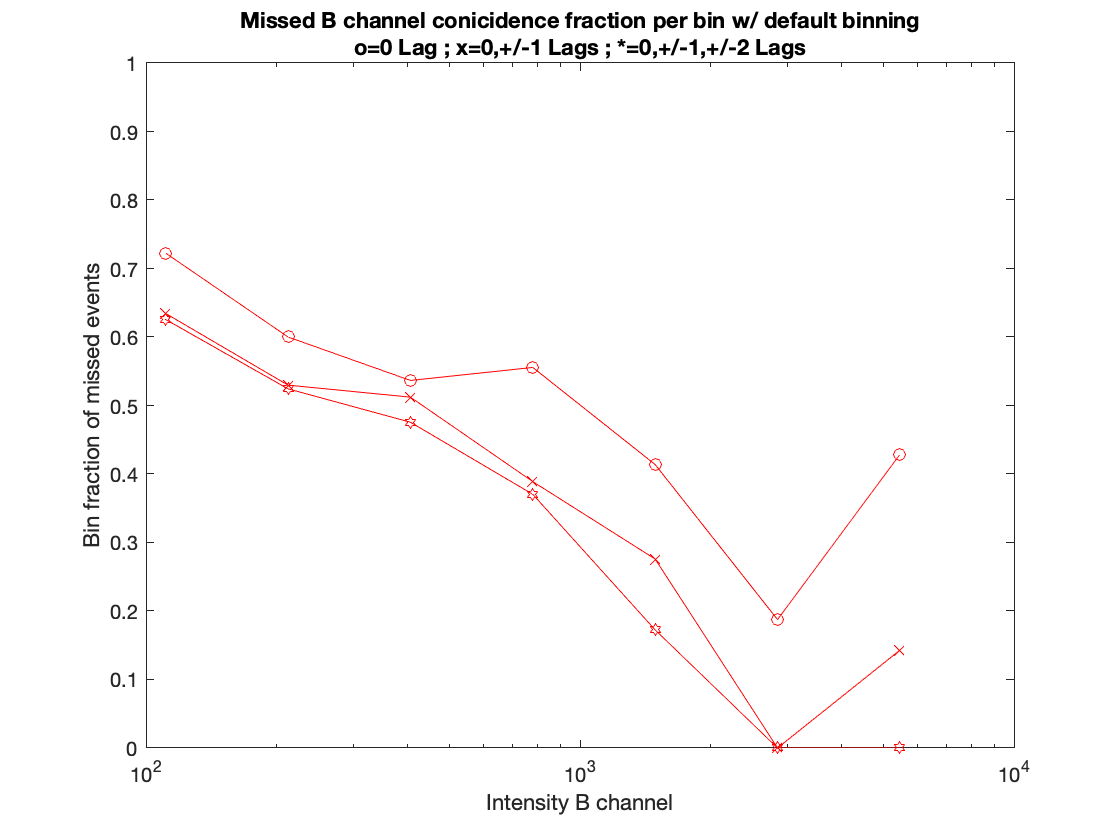



figure
[missB0_n,edges]=histcounts(handlesB.strikeamp(missindex0_B),logedgeB);
semilogx(logedgeB(1:end-1),missB0_n./nB(1:end-1),'-or'); 
hold on
[missB10_n,edges]=histcounts(handlesB.strikeamp(missindex10_B),logedgeB);
semilogx(logedgeB(1:end-1),missB10_n./nB(1:end-1),'-xr'); 
[missB210_n,edges]=histcounts(handlesB.strikeamp(missindex210_B),logedgeB);
semilogx(logedgeB(1:end-1),missB210_n./nB(1:end-1),'-hr'); 

subtitle=strcat("o=0 Lag ; x=0,+/-1 Lags ; *=0,+/-1,+/-2 Lags");
title({'Missed B channel conicidence fraction per bin w/ default binning';subtitle})
xlabel('Intensity B channel')
ylabel('Bin fraction of missed events')
ylim([0,1]); 
hold off

## Display ratio binned data as cumulative distribution

%First display the cumulative distribution plots for each ratio


%%nrows0=size(cumplot0BA,1);

MinEventsRatio0  =200

MinEventsRatio0 = 200

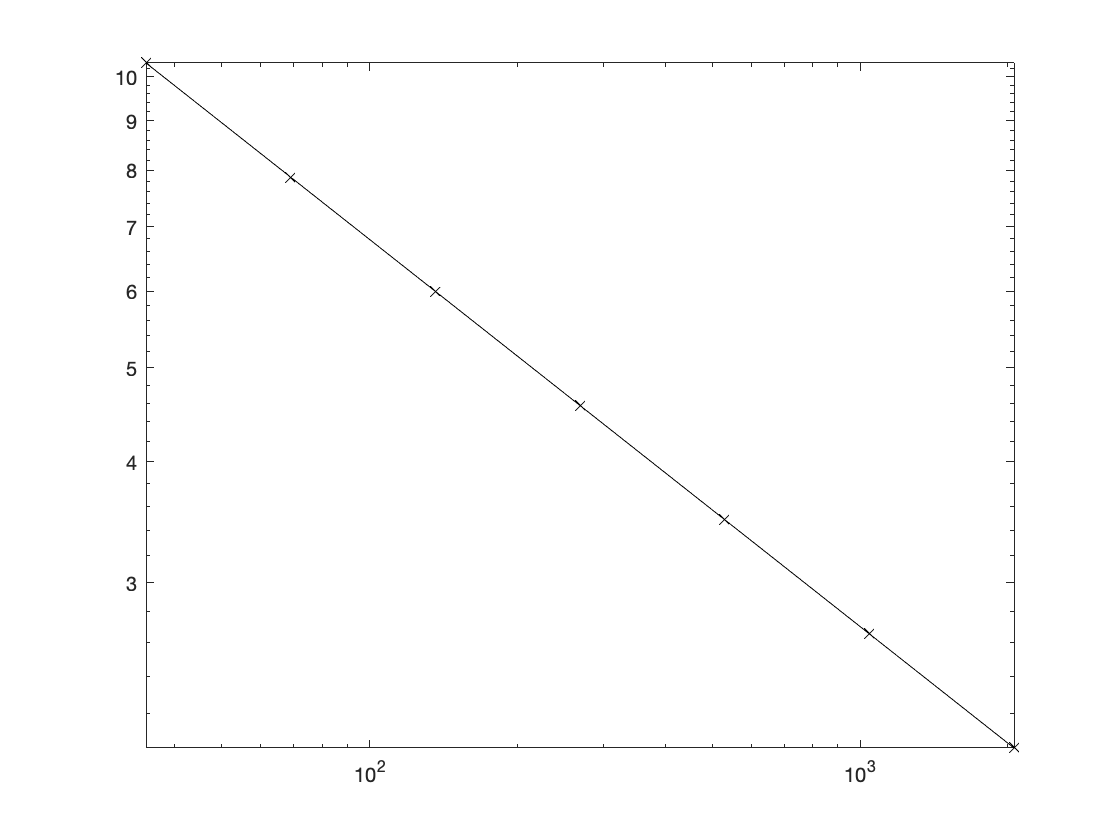

figure
%%show diagonals but start 3 in from corners to avoid 0's
for i=-size(avgn0BA,1)+3:size(avgn0BA,2)-3 
    diag0BA=diag(avgn0BA,i);
    diagIA=diag(IArat2D,i);
    if (sum(diag0BA)>MinEventsRatio0)
        loglog(diagIA,diag0BA)
        hold on
    end
end
%over plot a basic powerlaw model with index of powern as expected
powern =-0.4;

a=diag(avgn0BA,0);  b=diag(IArat2D,0); %center diagonal vectors
amid=a(fix(end/2)); %pin to middle data value
bmid=(b(fix(end/2))).^powern;
loglog(b,amid/bmid*(b).^powern,'-kx')

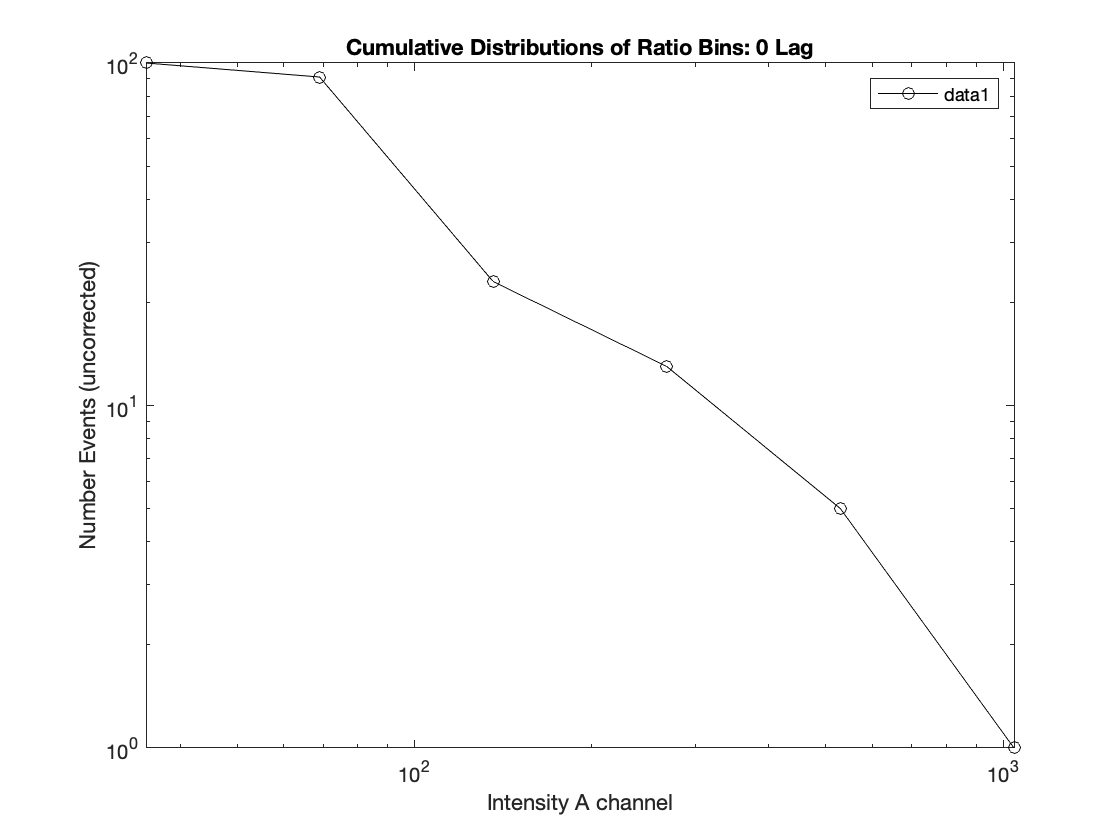


coadddiags0BA= sum(avgn0BA,2);
loglog(logedgeArb(1:end-1),coadddiags0BA,'-ok')


title('Cumulative Distributions of Ratio Bins: 0 Lag')
xlabel('Intensity A channel')
ylabel('Number Events (uncorrected)')
legend
                                                                                                                                                                                                    hold off



MinEventsRatio10  =200

MinEventsRatio10 = 200

figure
%%show diagonals but start 3 in from corners to avoid 0's
for i=-size(avgn10BA,1)+3:size(avgn10BA,2)-3 
    diag10BA=diag(avgn10BA,i);
    diagIA=diag(IArat2D,i);
    if (sum(diag10BA)>MinEventsRatio10)
        loglog(diagIA,diag10BA)
        hold on
    end
end
%over plot a basic powerlaw model with index of powern as expected
powern =-0.4;

a=diag(avgn10BA,0);  b=diag(IArat2D,0); %center diagonal vectors
amid=a(fix(end/2)); %pin to middle data value
bmid=(b(fix(end/2))).^powern;
loglog(b,amid/bmid*(b).^powern,'-kx')

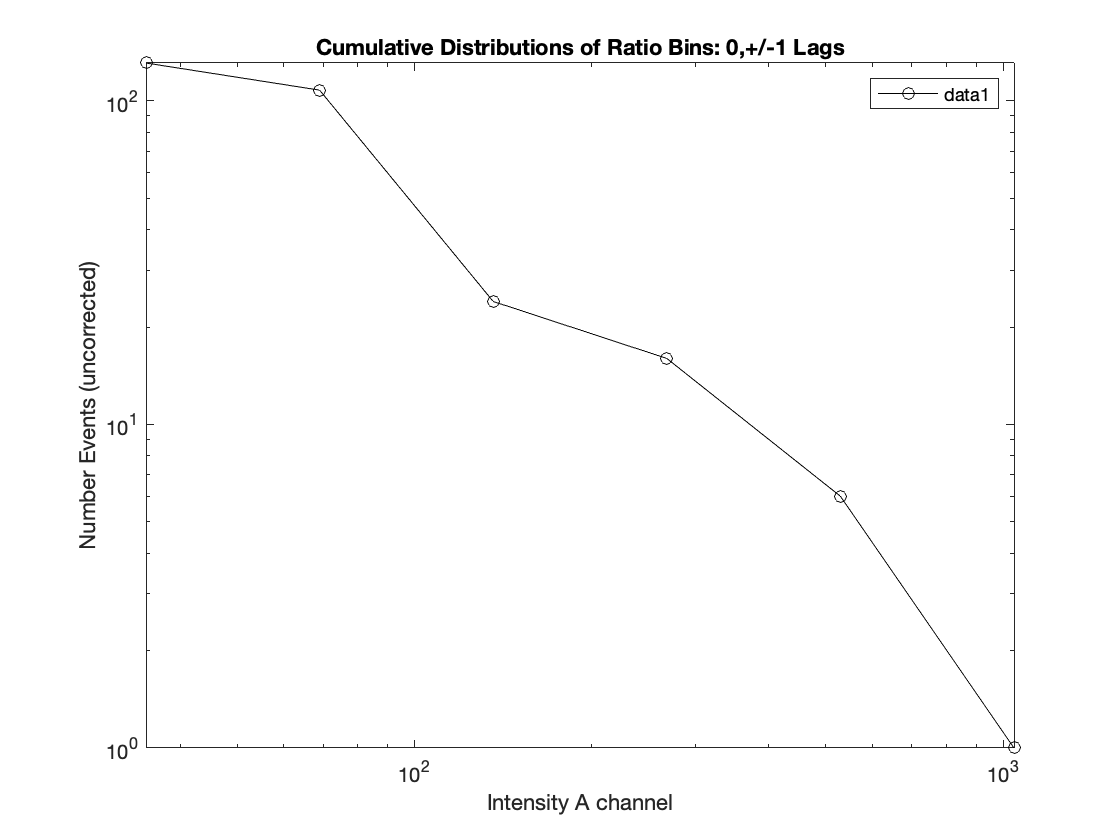


coadddiags10BA= sum(avgn10BA,2);
loglog(logedgeArb(1:end-1),coadddiags10BA,'-ok')

title('Cumulative Distributions of Ratio Bins: 0,+/-1 Lags')
xlabel('Intensity A channel')
ylabel('Number Events (uncorrected)')
legend
hold off



MinEventsRatio210  =200

MinEventsRatio210 = 200

figure
%%show diagonals but start 3 in from corners to avoid 0's
for i=-size(avgn210BA,1)+3:size(avgn210BA,2)-3 
    diag210BA=diag(avgn210BA,i);
    diagIA=diag(IArat2D,i);
    if (sum(diag210BA)>MinEventsRatio210)
        loglog(diagIA,diag210BA)
        hold on
    end
end
%over plot a basic powerlaw model with index of powern as expected
powern =-0.4;

a=diag(avgn210BA,0);  b=diag(IArat2D,0); %center diagonal vectors
amid=a(fix(end/2)); %pin to middle data value
bmid=(b(fix(end/2))).^powern;
loglog(b,amid/bmid*(b).^powern,'-kx')

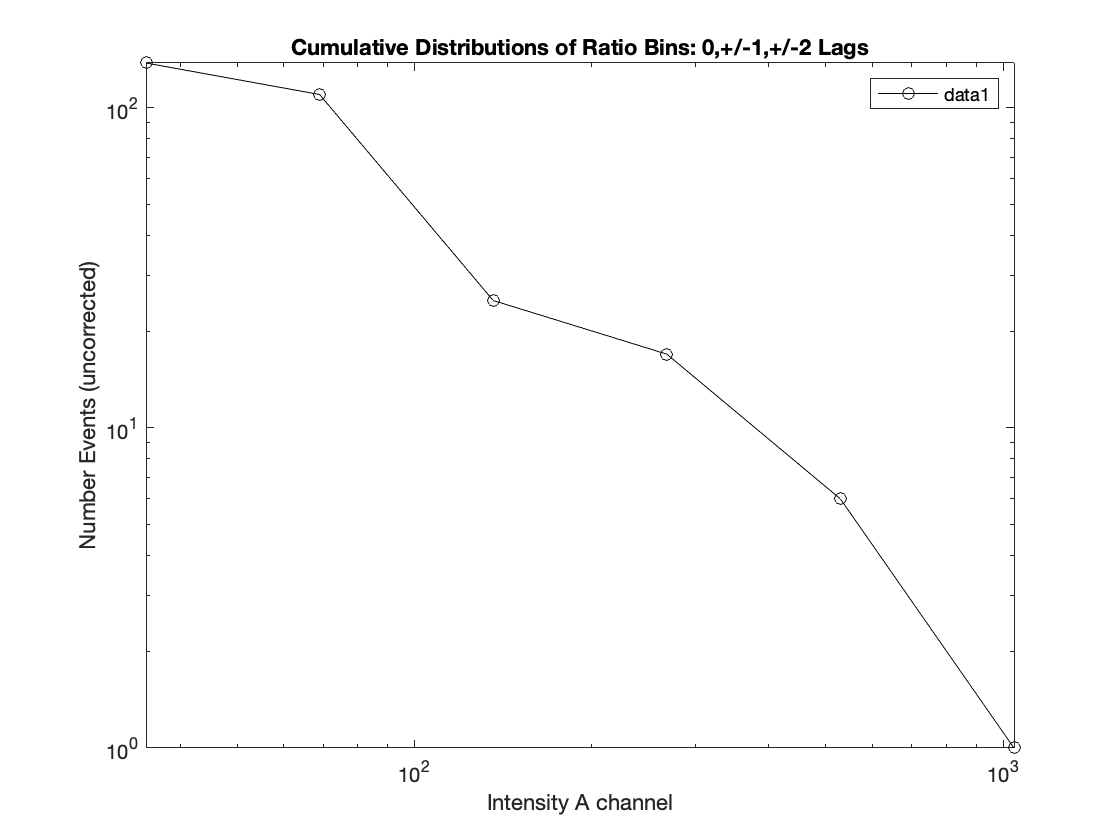


coadddiags210BA= sum(avgn210BA,2);
loglog(logedgeArb(1:end-1),coadddiags210BA,'-ok')

title('Cumulative Distributions of Ratio Bins: 0,+/-1,+/-2 Lags')
xlabel('Intensity A channel')
ylabel('Number Events (uncorrected)')
legend
hold off

## Calculate BAS correction to 2D binned data along diagonals (constant ratio)

For now, suppress simulated noise assessment

Processing diagonal:-7
Processing diagonal:-6
Processing diagonal:-5
Processing diagonal:-4
Processing diagonal:-3
Processing diagonal:-2
Processing diagonal:-1


Including ratio-1


Processing diagonal:0


Including ratio0


Processing diagonal:1


Including ratio1


Processing diagonal:2


Including ratio2


Processing diagonal:3


Including ratio3


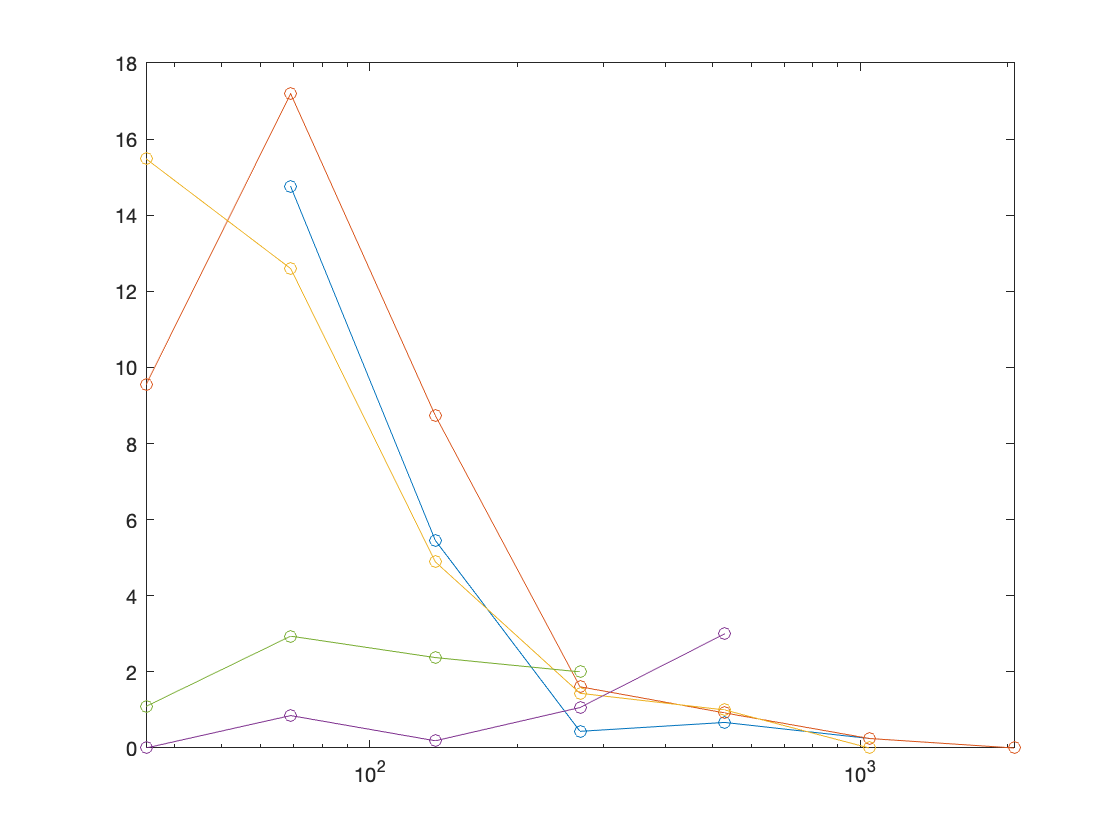

Processing diagonal:4
Processing diagonal:5
Processing diagonal:6
Processing diagonal:7


 % Generate multiple histograms using Gaussian distribtuion approx for each
 % bin where mean is nA or nB and sigma is uncertnA uncertnB
 
% numbassim = 1 % number of simulations to generate from bins
% uncertfactor = 2 % number sigma in gmdistrib about mean values nA

 
% Set up accessing index for diagonals (constant ratios) 
ndiag=size(avgn210BA,1)+size(avgn210BA,2)-1; %number of diagonals
    

% Initialize 2D BAS map
BASavgn210BA=avgn210BA*0;
BASunc210BA=unc210BA*0;
BAStemp=avgn210BA*0;  %temporary value holder
Nevents = sum(avgn210BA(:));

for i=-size(avgn210BA,1):size(avgn210BA,2) %index for diag distance from central; start 12 to 
                                            % have enough data for burst_analysis
                                            % i<0 is upper half on contour
                                            % plot==> truncates high
                                            % intensities
    disp(strcat('Processing diagonal: ',num2str(i)) );
    nrat=diag(avgn210BA,i)';
    uncrat=diag(unc210BA,i)';
    Irat=diag(IArat2D,i)';
    

% Find mean BAS values for this diaginal
    if sum(nrat(:)) > 0.05*sum(avgn210BA(:))
        disp(strcat('Including ratio',num2str(i)));
       plotlabelR= 'Mean BAS curve for each diagonal (fixed B/A ratio)';
       smooth = 1; showfigs = 0;
       [ numrat, qrat , cummrat] = burst_analysis( Irat, nrat , smooth, plotlabelR, showfigs);


% Load result back to diagonal; numrat should be same length as 
      semilogx(Irat,numrat','-o');
      hold on;
      BAStemp = diag(numrat',i);
      BASavgn210BA = BASavgn210BA + BAStemp;
    end
    
end

## Display contour map and pixel map of occupancy 

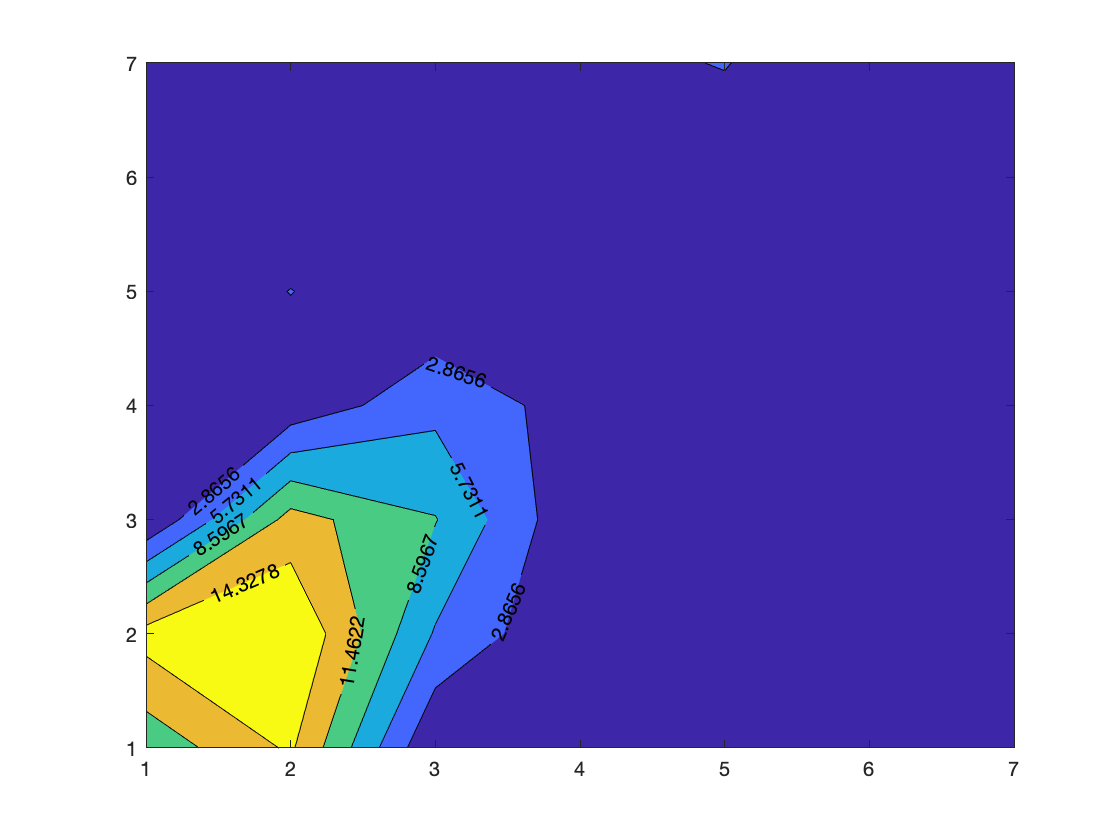

figure
contourf(BASavgn210BA',5,'Showtext','on'); %10 levels, transpose so A channel along horizontal

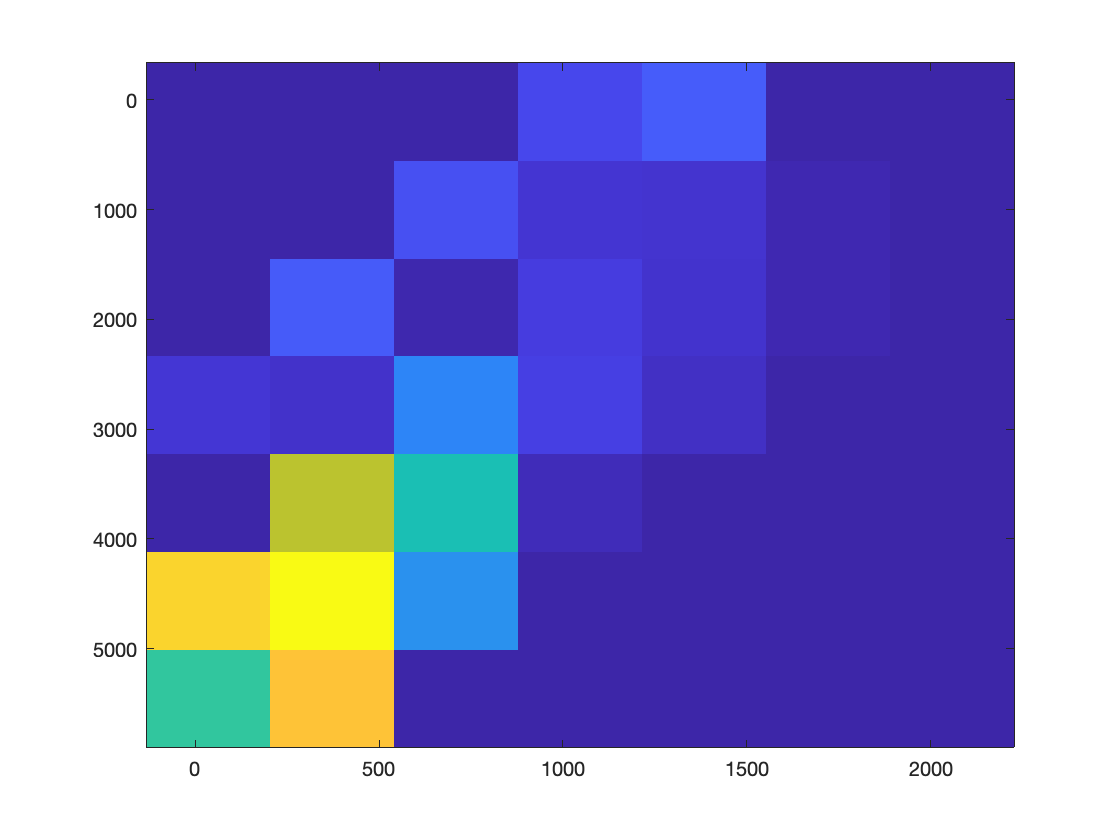

figure
imagesc(logedgeArb(1:end-1),logedgeBrb(1:end-1),flipud(BASavgn210BA'))



% Preview heat map of mcBAS contour plot
figure
[X,Y] = meshgrid(log10(logedgeArb(1:end-1)),log10(logedgeBrb(1:end-1)));
bz=BASavgn210BA'/sum(BASavgn210BA(:));   %Set to full range but normalized by what will be kept
contourf(10.^X*2000,10.^Y*2000,bz*0);   % Now in CPS units assuming 0.5 ms sampling

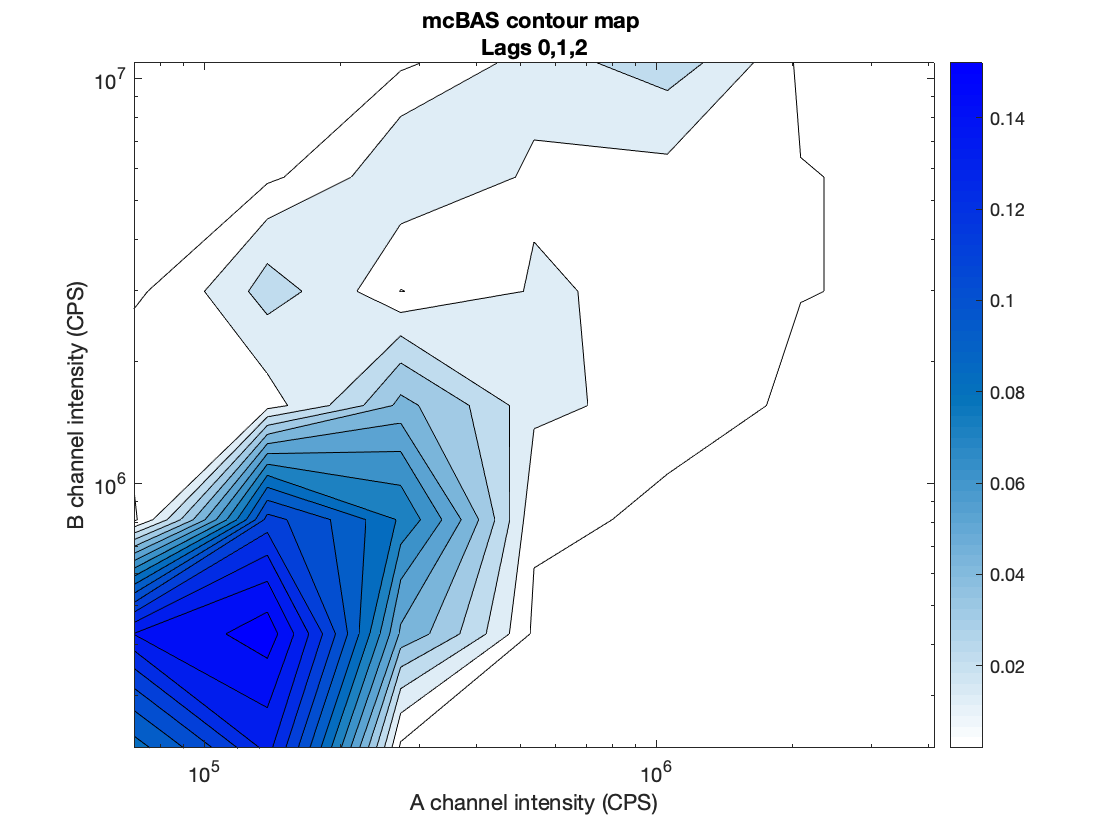

%splabel=strcat(plotlabel,'  |  coincid. cut ', string(per_cut_a),'%  |  cut bin: ',string(bin_cut_a));
%subtitle=splabel;
subtitle='Lags 0,1,2';
title({'mcBAS contour map ';subtitle});
xlabel('A channel intensity (CPS)');
ylabel('B channel intensity (CPS)');
hold on
xx=10.^X*2000;   % Now in CPS units
yy=10.^Y*2000;
set(gca,'XScale','Log','YScale','Log')
mx=max(max(bz));
clevels=[round(0.01*mx*1000):10:round(mx*1000)]/1000;   %Contour levels start at 1% of max value; lowest contour always 5%
contourf(xx,yy,bz,clevels);

set(gcf,'color','w');   % JP set boundary shading from default grey to white
colorbar;

ax = gca;
exportgraphics(ax,'HeatMap.eps','Resolution','600')


cm=[1 1 1;0.969444453716278 0.982969105243683 0.99167674779892;0.938888907432556 ...
    0.96593827009201 0.983353495597839;0.908333361148834 0.948907375335693 ...
    0.975030243396759;0.877777755260468 0.931876480579376 0.966706931591034; ...
    0.847222208976746 0.914845585823059 0.958383679389954;0.816666662693024 ...
    0.897814750671387 0.950060427188873;0.786111116409302 0.88078385591507 ...
    0.941737174987793;0.75555557012558 0.863752961158752 0.933413922786713; ...
    0.725000023841858 0.84672212600708 0.925090670585632;0.694444417953491 ...
    0.829691231250763 0.916767358779907;0.663888871669769 0.812660336494446 ... 
    0.908444106578827;0.633333325386047 0.795629501342773 0.900120854377747; ...
    0.602777779102325 0.778598606586456 0.891797602176666;0.572222232818604 ... 
    0.761567711830139 0.883474349975586;0.541666686534882 0.744536817073822 ... 
    0.875151097774506;0.51111114025116 0.72750598192215 0.866827845573425; ... 
    0.480555564165115 0.710475087165833 0.8585045337677;0.449999988079071 ... 
    0.693444192409515 0.85018128156662;0.419444441795349 0.676413357257843 ... 
    0.84185802936554;0.388888895511627 0.659382462501526 0.833534777164459; ... 
    0.358333319425583 0.642351567745209 0.825211524963379;0.327777773141861 ... 
    0.625320732593536 0.816888272762299;0.297222226858139 0.608289837837219 ... 
    0.808564960956573;0.266666680574417 0.591258943080902 0.800241708755493; ... 
    0.236111104488373 0.574228048324585 0.791918456554413;0.205555558204651 ...
    0.557197213172913 0.783595204353333;0.174999997019768 0.540166318416595 ... 
    0.775271952152252;0.144444450736046 0.523135423660278 0.766948699951172; ... 
    0.113888889551163 0.506104588508606 0.758625388145447;0.0833333358168602 ... 
    0.489073693752289 0.750302135944366;0.0527777783572674 0.472042798995972 ... 
    0.741978883743286;0.0222222227603197 0.455011934041977 0.733655631542206;... 
    0.0215053763240576 0.440334141254425 0.742247402667999;0.0207885317504406 ... 
    0.425656318664551 0.750839114189148;0.0200716853141785 0.410978525876999 ...
    0.759430885314941;0.0193548388779163 0.396300703287125 0.768022656440735; ... 
    0.0186379924416542 0.381622910499573 0.776614427566528;0.0179211478680372 ... 
    0.366945117712021 0.785206139087677;0.0172043014317751 0.352267295122147 ... 
    0.79379791021347;0.016487454995513 0.337589502334595 0.802389681339264; ... 
    0.015770610421896 0.322911709547043 0.810981392860413;0.0150537639856339 ... 
    0.308233886957169 0.819573163986206;0.0143369175493717 0.293556094169617 ... 
    0.828164935112;0.0136200720444322 0.278878271579742 0.836756706237793; ... 
    0.0129032265394926 0.264200478792191 0.845348417758942;0.0121863801032305 ... 
    0.249522671103477 0.853940188884735;0.0114695345982909 0.234844863414764 ... 
    0.862531960010529;0.0107526881620288 0.220167070627213 0.871123671531677;... 
    0.0100358426570892 0.205489262938499 0.879715442657471;0.0093189962208271 ... 
    0.190811455249786 0.888307213783264;0.00860215071588755 0.176133647561073 ... 
    0.896898925304413;0.00788530521094799 0.161455854773521 0.905490696430206; ... 
    0.00716845877468586 0.146778047084808 0.914082467556;0.0064516132697463 ... 
    0.132100239396095 0.922674238681793;0.00573476729914546 0.117422431707382 ...
    0.931265950202942;0.00501792132854462 0.10274463146925 0.939857721328735; ...  
    0.00430107535794377 0.0880668237805367 0.948449492454529;0.00358422938734293 ... 
    0.0733890235424042 0.957041203975677;0.00286738364957273 0.0587112158536911 ... 
    0.965632975101471;0.00215053767897189 0.0440334118902683 0.974224746227264; ... 
    0.00143369182478637 0.0293556079268456 0.982816517353058;0.000716845912393183 ... 
    0.0146778039634228 0.991408228874207;0 0 1];
colormap(cm);   %JP  Blue color map for paper

## Allow coarser binning for better sampling of ratios

(rows,col)

% rebinfacA = 2
% rebinfacB = 1
% 
% xq = (0:5/6:sz(1))';
% yq = (0:5/6:sz(2))';
% vq = uint8(F({xq,yq}));
% imshow(vq)


## Save results to .mat file and a pdf report

savecoinresults=true

savecoinresults = logical
   1


%Save processing 
%Get information about this data run and create a director for this data store
[coinfile, tstr]=Information(versionnum);

tstr = datetime
   06Jan22-182500


version number:v1p4


timestr=string(tstr);
newdir=strcat(coinfile,'_',timestr)

newdir = "COIN_v1p4_06Jan22-182500"

mkdir(newdir)


if savecoinresults
   savecoindone=Save_COIN(newdir,PrePathName,PreFileName,handlesA,handlesB,logedgeA, logedgeB, logedgeArb,logedgeBrb, ...
       nA, nB, X, Y, BASavgn210BA, xx, yy, bz, versionnum)
end

tstr = datetime
   06Jan22-182500


version number:v1p4


savecoindone = 1

# Part II

## FUNCTIONS

## Determine photon histogram

function [logedge,n,uncertn]=photon_hist(handles,datastat,nbins,minthresh,maxthresh,tbin,ptype,nseg,part)
% Calculate photon count histogram with input binning parameters 
% returns binning left edges, number in bin and estimate of uncertainty in binning 
% tbin =  size of bins in seconds
% ptype choose linear or logarithmic binning; use log for usual BAS
% now
% nseg
% part

peakloc=find(handles.strikeamp > 0);  %indicies to all events found
peakloc=peakloc(find(peakloc > 15)); %find only events +/- 15 bins from ends
peakloc=peakloc(find(peakloc < size(handles.strikeamp,2)-15));
npeaks=size(peakloc,2);  % Number of peaks to consider

%params=struct('mean',[1:npeaks],'sig',[1:npeaks],'A',[1:npeaks]);

peaks=handles.strikeamp(peakloc); %not really needed, just saves typing

edgemn=(log10(minthresh));
edgemx=(log10(maxthresh));

%edgeexp=[edgemn:edgemx];
logedge = logspace(edgemn,edgemx,nbins);
disp(strcat("Bin edges: ",num2str(logedge)))

if (ptype == 'Linear') 
    [n,xbins]=hist(peaks,nbins);
    figure
    loglog(xbins,n,'ro');
    title(strcat("Burst histogram with linear binning: ",num2str(nbins)," bins"))
    xlabel('Intensity (counts)')
    ylabel('Number in bin')
else
%    [n,xbins]=histc(peaks,logedge); %older 2013 command
    [n,edges,xbins]=histcounts(peaks,logedge); %histcounts returns logedege into
    % edges and xbins is as before; n has 1 fewer elements so use
    % logedge(1:end-1) below
    figure
    loglog(logedge(1:end-1),n,'ro');
%Find an estimate of uncertainties in each bin by breaking  data set into
%quarters
    quar=fix(length(peaks)/4);
    [nq1,edges]=histcounts(peaks(1:quar),logedge);
    [nq2,edges]=histcounts(peaks(quar+1:2*quar),logedge);
    [nq3,edges]=histcounts(peaks(2*quar+1:3*quar),logedge);
    [nq4,edges]=histcounts(peaks(3*quar+1:end),logedge);
    avnq =(nq1+nq2+nq3+nq4)/4; %avg quadrature number of events
    unc=sqrt(((nq1-avnq).^2+(nq2-avnq).^2+(nq3-avnq).^2+(nq4-avnq).^2)/4);
    uncertn=4*unc; %uncertainty estimate for full data bins
    hold on
    loglog(logedge(1:end-1),n+uncertn,'rx');  
    loglog(logedge(1:end-1),n-uncertn,'rx');  
    hold off
    
    logedge=logedge(1:end-1); %so that only bin left edges are passed back


%over plot a basic powerlaw model with index of powern as expected
powern =-0.4;

a=n(3); %pin to third data value - first sometimes compromised by binning
b=(logedge(3)).^powern;
hold on
loglog(logedge(1:end-1),a/b*(logedge(1:end-1)).^powern,'-bx')
hold off
subtitle=strcat("Fit Poewerlaw of index: ",num2str(powern));
    title(strcat("Burst histogram with log binning: ",num2str(nbins)," bins"))
    xlabel('Intensity (counts)')
    ylabel('Number in bin')
    legend('Event Histogram','1sig Upper Bound','1sig Lower Bound', 'Powerlaw Model','Location','northeast')


end

end


## Calculate BAS distribution

Exactly from burst_analysis_JP.m used for MCBAS paper

function [ num, q , cumm] = burst_analysis( logedge, n , smooth, plotlabel, showfigs)
%This program runs burst analysis and outputs the event density
% Plotlabel is a string added to PCH diagnostic figure 
% smooth:  1 or anything else .   1 means use smoothing function on PCH before BAS
% plotlabel:   a string to be added to plots that indicates data type, name, etc.
% singlecolor:  1 or anything else . 1 means single color BAS so display more plots
% 

sx=logedge;
sn=n;
ind=.40;  %Set by Tetraspec beads 28 Aug 2020
    
%sn=smooth(sx,sn,'lowess');  %rlowess will round off steep spectra
%sn=sn';

if (smooth == 1)
    [sn,sx]=burst_smooth_JP(sx,sn,plotlabel,showfigs);
%    [sn,sx]=burst_smooth(sx,sn);
end
%sx=sx(1:(end-1));
% save 'inter_sn.mat' sn;

%Extend vector length  to 28 by padding with zeros
ngood=size(sx(:),1);
ndew=28-ngood;
if (ndew > 0)
    pad=ones(ndew,1)/100;
    sx=[pad'/1e6,sx]';
    sn=[pad',sn]';
end

%x=logedge(1:28)';
%y=n';
xfer=1./(sx.^ind);
mask0=zeros(1,28);
mask1=ones(1,28);
%mod=xfer;
mod=mask1';
for i=27:-1:1
    mask_i=[mask1(1:i),mask0(i+1:end)]';
%    mod=[mod xfer.*mask_i];
    mod=[mask_i mod];  %I reversed this from before because amp was reversed
end %for

%a=mod\n;


%Use of FIT routine
x=sx; y=sn;
 formula_a='(a1*m1+a2*m2+a3*m3+a4*m4+a5*m5+a6*m6+a7*m7+a8*m8+a9*m9+a10*m10+a11*m11+a12*m12)./(x.^0.40)';
 formula_b='(a13*m13+a14*m14+a15*m15+a16*m16+a17*m17+a18*m18+a19*m19+a20*m20+a21*m21+a22*m22+a23*m23+a24*m24)./(x.^0.40)';
 formula_c='(a25*m25+a26*m26+a27*m27+a28*m28)./(x.^0.40)';
 formula=[formula_a,'+',formula_b,'+',formula_c];
 mymodel = fittype(formula,'problem',{'m1','m2','m3','m4','m5','m6','m7','m8','m9','m10','m11','m12', ...
     'm13','m14','m15','m16','m17','m18','m19','m20','m21','m22','m23','m24','m25','m26','m27','m28' });
 opts = fitoptions(mymodel);
 opts.Lower=zeros(1,28);
 
 %%%%
 opts.Robust='Bisquare';
 opts.MaxFunEvals=10000;
 %%%%
 %%opts.Upper=max(y'.*(x'.^0.40)/15,ones(1,28)); %%max(y'/5,ones(1,28));
 opts.Upper=10000*ones(1,28); 
 opts.Weights=ones(1,28); opts.Weights(1:ndew)=0; %Unweight padded values
 opts.Startpoint=ones(1,28);
% get(opts); %print out options
[fit4,gof4,out4] = fit(x,y,mymodel,opts,'problem',{mod(:,1),mod(:,2),mod(:,3),mod(:,4),mod(:,5),mod(:,6), ...
   mod(:,7),mod(:,8),mod(:,9),mod(:,10),mod(:,11),mod(:,12), ... 
   mod(:,13),mod(:,14),mod(:,15),mod(:,16),mod(:,17),mod(:,18), ...
   mod(:,19),mod(:,20),mod(:,21),mod(:,22),mod(:,23),mod(:,24),...
   mod(:,25),mod(:,26),mod(:,27),mod(:,28)});

amp=[fit4.a1,fit4.a2,fit4.a3,fit4.a4,fit4.a5,fit4.a6,fit4.a7,fit4.a8,fit4.a9,fit4.a10,...
    fit4.a11,fit4.a12,fit4.a13,fit4.a14,fit4.a15,fit4.a16,fit4.a17,fit4.a18,fit4.a19,fit4.a20,...
    fit4.a21,fit4.a22,fit4.a23,fit4.a24,fit4.a25,fit4.a26,fit4.a27,fit4.a28];

%amp=amp.*opts.weights;
%reverse order because mod's are reversed in order - fix later
%ord=[28:-1:1];
%amp=amp(ord);
% Remove padding
amp=amp(ndew+1:end);
sx=sx(ndew+1:end); sn=sn(ndew+1:end); xfer=xfer(ndew+1:end);


del=zeros(1,ngood);
for i=ngood-1:-1:1
    del(i)=xfer(i)*sum(amp(i+1:end));
%    del(i)=xfer(i)*sum(sn(i+1:end)./xfer(i+1:end));
end; %for

del=del';
rv=[ngood:-1:1];
q=fit4(x); q=q(ndew+1:end);
%nn=xfer.*(amp); %Same as num except with correction for log binning
nn=xfer.*(amp'); %Same as num except with correction for log binning

num=q-del;  %net number of events in each bin corrected for larger species
cumm=cumsum(q(rv)-del(rv)); %cumulative sum from largest to smallest
cumm=cumm(rv); %reorder for plotting
% save 'inter_q.mat' q;
% save 'inter_1BAS.mat' q cumm num sx sn;

% Display some figures
if (showfigs)
        
    figure
    loglog(sx,sn,'-bo');  %original PCH data
    hold on
    loglog(sx,q,'-r');  %BAS model fit
    subtitle = plotlabel;
    title({'PCH binned data & BAS model fit';subtitle})
    set(gca,'XLim',[sx(1),sx(end)]);
    xlabel('Intensity')
    ylabel('Number Events (uncorrected)')
    legend('PCH','BAS Model fit');
    hold off
% 
%     figure
%     loglog(sx,num,'-bo');  %BAS number density
%     title('BAS corrected Number Density vs Intensity')
%     suptitle(plotlabel)
%     xlabel('Intensity')
%     ylabel('Number Events (BAS Corrected)')
%     set(gca,'YLim',[1,1000],'XLim',[sx(1),sx(end)]);
%     legend('BAS data');
% 
    
end

end

## Smooth Raw Event Histogram before BAS

Code taken direct from burst_smooth_JP.m

function [sns,sx] = burst_smooth_JP(sx,sn,plotlabel,showfigs)
% Take in PCH data that is LOGARYTHMICALLY binnned then extrapolate a next
% lower intensity event number for sn. Use this to apply Daniel's smoothing 
% filter. Concern is that that filter systematically lowers value of first
% bin causing BAS to show population drop that isn't real. Also, the filter
% removed the largest intensity bin. Here the extrapolation mostly removes
% low intensity bias but largest bin is still lost so original data largest
% bin is simply concatenated. This could be an issue for a spuriously large
% value of events in largest bin.

dlogbin=mode(diff(log10(sx(:))));  %Find logrythmic spacing between bins
%This means log10(sx(n))-log10(sx(n-1))=dlogbin
%or sx(n-1)=sx(n)/(10^dlogbin)
% Use this to extrapolate the next lower intensity bin
extrapbin=sx(1)/(10^dlogbin);

%Use spline interp to estimate a continuance of sn data
x=sx;
y=sn;
extrapx=[extrapbin,sx];
nexty=max([csapi(x,y,extrapbin),y(1),y(2)]); %Follow data trend up and prevents downward
extrapy=[nexty,sn];

if (showfigs)
    figure
    loglog(sx,sn,'-bo');  %original DATA
    hold on
    loglog(extrapx,extrapy,'-rx');   % include extrapolated smaller point
    subtitle = plotlabel;
    title({'Smoothed PCH binned data w/ extrapolated smallest bin';subtitle})
    xlabel('Intensity')
    ylabel('Number Events (uncorrected)')
    set(gca,'XLim',[extrapx(1),extrapx(end)]);
end;

% Daniel's averaging method that biases down first data point (hence
% extrapolation). Also, largest intensity bin lost in this averaging so add
% min of original last sn and new extrapolate 2nd to last data value. 

avglow=(extrapy(1:(end-1))+extrapy(2:end))/2;
avghi=[extrapy(1),avglow];
avgn=(avglow+avghi(1:end-1))/2;
sns=[avgn,min(sn(end-1),sn(end))];  %Add a last data value consistent with 
% original data unless larger than smoothed last value - prevents aphysically 
%large 1st value

if (showfigs)
    %Add smooth to PCH to see if it looks ok
    loglog(extrapx(2:end),sns(2:end),'-g+');
    legend('Original','Extrapolated','Smoothed')
end;

%%Time to examine smooth result
pause(3)

%Continue with smooth PDH data removing 1st extrapolated point
sns=sns(2:end);  

end


## Outputs code version information 

function [coinfile, tstr]=Information(versionnum)
% Display version and hold introductory information


coinfile=strcat('COIN_',versionnum);

tstr=datetime('now');
tstr.Format = 'ddMMMyy-HHmmss'

disp(strcat('version number: ',versionnum))

end



## Save Coincidence results to .mat and PDF report

function savepredone=Save_COIN(newdir,PrePathName,PreFileName,handlesA,handlesB,logedgeA, logedgeB, logedgeArb,logedgeBrb, ...
       nA, nB, X, Y, BASavgn210BA, xx, yy, bz, versionnum)
% save data and results

[coinfile, tstr]=Information(versionnum);

timestr=string(tstr);
coinfilenamereport=strcat(PrePathName,newdir,'/',coinfile,PreFileName,timestr,'OUTPUT.pdf');
coinfilenamesave=strcat(PrePathName,newdir,'/',coinfile,PreFileName,timestr,'RESULTS.mat');
coinfilenameprog=strcat(PrePathName,newdir,'/',coinfile,PreFileName,timestr,strcat(coinfile,'.mlx'));
        
% % Write our a run report PDF
% %import matlab.internal.liveeditor.LiveEditorUtilities
% matlab.internal.liveeditor.openAndConvert(which(string(prefilenameprog)),char(prefilenamereport));

%Save all Matlab variables and states
save(coinfilenamesave)
savepredone=1;
end
